% syms t1 t2 t3 t4 t5 t6 real;
% 
% % Read angles from CSV file
% anglesList = readtable('mazeangles.csv');
% 
% % Convert table to matrix and convert to radians
% anglesList_rad = deg2rad(table2array(anglesList));
% 
% % Load the robot from the URDF file
% robot = importrobot("E:\ras\project\project\TEST_files\Final_files\my_pro600.urdf");
% figure(1);
% config = homeConfiguration(robot);
% show(robot, config);
% 
% % Set up the figure
% view(-100, 90);
% axis([-1 1 -1 1 0 1.5]);
% grid on;
% hold on; % To retain plots
% camzoom(1.20);
% h = light('Style', 'infinite', 'Position', [0.2, 0.7, 0.9], 'Color', [1, 1, 1]);
% p = light('Style', 'local', 'Position', [-0.4, -0.7, -0.9], 'Color', [1, 1, 1]);
% 
% % Animation parameters
% totalDuration = 0.1;  % 5 seconds for each movement
% frameRate = 60;  % 60 frames per second
% nSteps = totalDuration * frameRate;
% 
% % Initialize the path array for storing end-effector positions
% path = [];
% 
% % Function to compute the end-effector position
% function pos = getEndEffectorPosition(robot, config)
%     tform = getTransform(robot, config, 'link6', 'base_link'); % Adjust 'tool0' if the end-effector link is named differently
%     pos = tform(1:3, 4); % Extract the XYZ position
% end
% 
% % Function to animate movement
% function path = animateMovement(robot, startAngles, endAngles, nSteps, frameRate, path)
%     for i = 0:nSteps
%         alpha = i / nSteps;
%         config = homeConfiguration(robot); % Start with a valid configuration structure
%         for j = 1:numel(config)
%             config(j).JointPosition = (1-alpha) * startAngles(j) + alpha * endAngles(j);
%         end
%         show(robot, config, 'PreservePlot', false);
%         % Compute the end-effector position
%         pos = getEndEffectorPosition(robot, config);
%         path = [path; pos']; % Append the position to the path
%         % Plot the path
%         plot3(path(:, 1), path(:, 2), path(:, 3), 'r-', 'LineWidth', 2);
%         drawnow;
%         pause(1 / frameRate);
%     end
% end
% 
% % Animate through all angle sets
% disp('Starting simulation...');
% currentAngles = zeros(1, 6); % Start at home position [0,0,0,0,0,0]
% for k = 1:size(anglesList_rad, 1)
%     targetAngles = anglesList_rad(k, :);
%     disp(['Moving to position ', num2str(k), '...']);
%     path = animateMovement(robot, currentAngles, targetAngles, nSteps, frameRate, path);
%     currentAngles = targetAngles; % Update current angles
%     pause(2); % Pause between movements
% end
% 
% % Remove the robot and retain the path
% disp('Removing the robot and retaining the path...');
% cla; % Clear the axes (removes robot and lights)
% plot3(path(:, 1), path(:, 2), path(:, 3), 'r-', 'LineWidth', 2); % Re-plot the path
% axis([-1 1 -1 1 0 1.5]);
% grid on;
% view(-100, 90);
% title('Robot Path');
% xlabel('X');
% ylabel('Y');
% zlabel('Z');
% 
% % Save the final path image
% disp('Saving the final path image...');
% saveas(gcf, 'robot_path_only.png');
% disp('Simulation complete. Path image saved as "robot_path_only.png".');


%% simulate_from_ik_results.m
% This script reads a CSV file generated by the Python code (e.g., ik_results.csv),
% where the CSV contains columns: timestamp, world_x, world_y, world_z, and Joint1.
% The Joint1 column contains a string with all joint angles (e.g., "[-1.31655,...]").
% The script parses these joint angles, loads the robot from its URDF, and animates
% the robot moving through the recorded configurations while plotting the end‐effector path.
% The final path image is saved as "robot_path_only.png".

%% Read and parse joint angle data from CSV
anglesTable = readtable('ik_results.csv');

% Extract the Joint1 column (which is a cell array of strings)
jointStrs = anglesTable.("Joint1");
nConfigs = height(anglesTable);
anglesList = zeros(nConfigs, 6);  % Preallocate matrix for 6 joint angles per configuration

for i = 1:nConfigs
    str = jointStrs{i};  % e.g., "[-1.316553110402228,-2.808937981721314,7.072603590749833e-08,-1.9256672312669945,-1.5620958734791737,-0.25414657503451293]"
    % Use str2num to convert the string into a numeric vector
    angles = str2num(str);  %#ok<ST2NM>
    if isempty(angles) || numel(angles) ~= 6
        error('Could not parse joint angles on row %d', i);
    end
    anglesList(i,:) = angles;
end

%% Load the robot from the URDF file
robot = importrobot("E:\ras\project\project\TEST_files\Final_files\my_pro600.urdf");
robot.DataFormat = 'struct';  % Use configuration structure
figure(1);
initialConfig = homeConfiguration(robot);
show(robot, initialConfig);
title('Initial Robot Configuration');

%% Set up the figure for simulation
view(-100, 90);
axis([-1 1 -1 1 0 1.5]);
grid on;
hold on;       % Retain plots between frames
camzoom(1.20);
light('Style', 'infinite', 'Position', [0.2, 0.7, 0.9], 'Color', [1, 1, 1]);
light('Style', 'local', 'Position', [-0.4, -0.7, -0.9], 'Color', [1, 1, 1]);

%% Animation parameters
totalDuration = 0.1;  % Duration (in seconds) for each movement segment
frameRate = 60;       % Frames per second
nSteps = totalDuration * frameRate;

%% Initialize the path array for storing end-effector positions
path = [];

%% Helper function to compute the end-effector position
function pos = getEndEffectorPosition(robot, config)
    % Compute transform from 'base_link' to end-effector link ('link6')
    tform = getTransform(robot, config, 'link6', 'base_link');
    pos = tform(1:3, 4);  % Extract the XYZ position
end

%% Helper function to animate movement between two configurations
function path = animateMovement(robot, startAngles, endAngles, nSteps, frameRate, path)
    % startAngles and endAngles are numeric row vectors (1x6)
    for i = 0:nSteps
        alpha = i / nSteps;
        % Get a copy of the home configuration
        config = homeConfiguration(robot);
        % Interpolate each joint position between start and end angles
        for j = 1:numel(config)
            config(j).JointPosition = (1 - alpha) * startAngles(j) + alpha * endAngles(j);
        end
        % Update robot visualization (clear previous plot)
        show(robot, config, 'PreservePlot', false);
        % Compute end-effector position and append to path
        pos = getEndEffectorPosition(robot, config);
        path = [path; pos'];  % Append as a new row
        % Plot the path in red
        plot3(path(:, 1), path(:, 2), path(:, 3), 'r-', 'LineWidth', 2);
        drawnow;
        pause(1 / frameRate);
    end
end

%% Animate the robot through all joint angle sets from the CSV
disp('Starting simulation...');

Starting simulation...


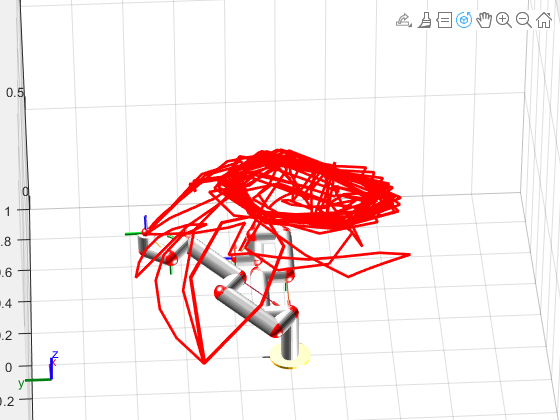

Moving to configuration 1...
Moving to configuration 2...
Moving to configuration 3...
Moving to configuration 4...
Moving to configuration 5...
Moving to configuration 6...
Moving to configuration 7...
Moving to configuration 8...
Moving to configuration 9...
Moving to configuration 10...
Moving to configuration 11...
Moving to configuration 12...
Moving to configuration 13...
Moving to configuration 14...
Moving to configuration 15...
Moving to configuration 16...
Moving to configuration 17...
Moving to configuration 18...
Moving to configuration 19...
Moving to configuration 20...
Moving to configuration 21...
Moving to configuration 22...
Moving to configuration 23...
Moving to configuration 24...
Moving to configuration 25...
Moving to configuration 26...
Moving to configuration 27...
Moving to configuration 28...
Moving to configuration 29...
Moving to configuration 30...
Moving to configuration 31...
Moving to configuration 32...
Moving to configuration 33...
Moving to configura

% Start at home configuration (assumed to be zeros)
currentAngles = zeros(1, 6);
for k = 1:size(anglesList, 1)
    targetAngles = anglesList(k, :);
    disp(['Moving to configuration ', num2str(k), '...']);
    % Animate from current configuration to the target configuration
    path = animateMovement(robot, currentAngles, targetAngles, nSteps, frameRate, path);
    % Update currentAngles for the next interpolation
    currentAngles = targetAngles;
    pause(2);  % Pause between movements for observation
end


%% Finalize the simulation visualization
disp('Finalizing simulation: Retaining only the end-effector path...');

Finalizing simulation: Retaining only the end-effector path...


cla;  % Clear the axes (removes robot and lights)
plot3(path(:, 1), path(:, 2), path(:, 3), 'r-', 'LineWidth', 2);  % Re-plot the end-effector path
axis([-1 1 -1 1 0 1.5]);
grid on;
view(-100, 90);
title('Robot End-Effector Path');
xlabel('X');
ylabel('Y');
zlabel('Z');

%% Save the final path image to a file
disp('Saving the final path image...');

Saving the final path image...


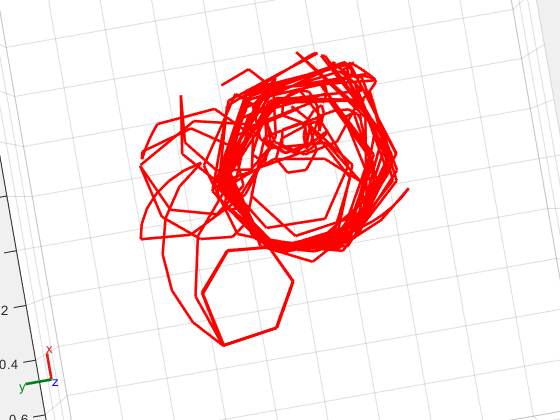

saveas(gcf, 'robot_path_only.png');

disp('Simulation complete. Path image saved as "robot_path_only.png".');

Simulation complete. Path image saved as "robot_path_only.png".
